## 0. Initialization

**Cleaning the environment**

clear; close all; clc;

**Installation and import**

Download and unzip the content of the folder `'LoopDetect_for_Matlab'`. Within the MATLAB session, navigate to this folder and work there or add the path of the folder to MATLAB's search path for the current MATLAB session by MATLAB's `addpath()` function. Deending on where you stored the folder, its name could be something like `'/Users/Desktop/LoopDetect' `on Mac or `'C:\matlab\LoopDetect'` on Windows.

% Retrieve the LoopDetect folder location when having navigated to the folder
% within the MATLAB session.
LoopDetect_Folder_Name = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'loopdetect_for_matlab');
LoopDetect_Folder_Name = char(java.io.File(LoopDetect_Folder_Name).getCanonicalPath); % normalize path
addpath(LoopDetect_Folder_Name);

**Models:**

Models = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'models');
Models = char(java.io.File(Models).getCanonicalPath); % normalize path
addpath(Models);

## 1. Model

This model for complex formation (4 species) is already implemented with the name as ``func_kho00`` and ``func_kho00_nofb``, provided by Prof. Baum, saved in the path for models as above.

Parameters:

% Parameters from supplementary material
% Parameters (klin)
klin = [ ...
    2.5   % k1
    0.25  % k2
    0.025 % k3
    0.025 % k4
    0.75  % k5
    0.75  % k6
    0.025 % k7
    0.025 % k8
    0.5   % k9
    0.5   % k10
];

% Parameters (kn)
kn = [ ...
    9   % kn1 = KI
    10  % kn2 = K1
    8   % kn3 = K2
    15  % kn4
    15  % kn5
    15  % kn6
    15  % kn7
    15  % kn8
    15  % kn9
    15  % kn10
    15  % kn11
    1   % n1 (power param)
];

% Initial conditions
initial_conditions = [ ...
    100  % S1: MKKK, MAPKKK
    0    % S2: MKKK-P, MKKK*
    300  % S3: MKK, MAPKK
    0    % S4: MKK-P, MAPKK*
    0    % S5: MKK-PP, MAPKK**
    300  % S6: MAPK, MAPK
    0    % S7: MAPK-P, MAPK*
    0    % S8: MAPK-PP, MAPK**
];


## 2. Result reproduction

### Temporal dynamics

Solving the ODE model to observe temporal dynamics

Intial stimulation to stablize the system

tspan = linspace(0, 3650, 3651);
opts = odeset('RelTol',1e-6,'AbsTol',1e-9);  % closer to typical SciPy accuracy
[t,sol] = ode15s(@(t,x) func_kho00(t,x,klin, kn), tspan, initial_conditions, opts);
s_star_2=sol(end,:); %the last point of the simulation is chosen

Plot

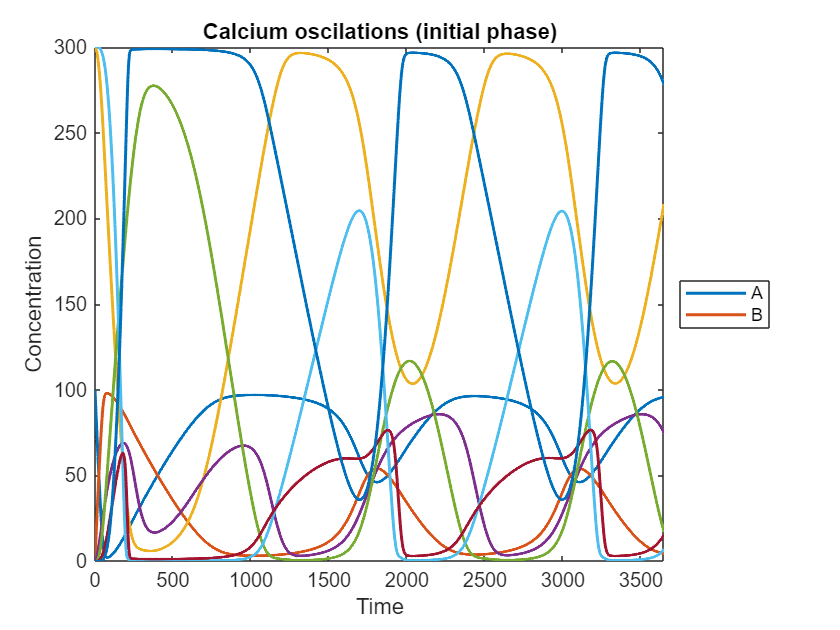

figure;
plot(t, sol, 'LineWidth', 1.5);
%xline(t_perb, '--', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Concentration');
xlim([0,3650]);
% ylim([0,2]);
title('Calcium oscilations (initial phase)');
legend('A','B','Location','eastoutside'); % southeast

Now, when the system have stable trajectories, draw temporal dynamics for t=[0, 5000].

tspan = linspace(0, 5000, 5001);
[t,sol] = ode15s(@(t,x) func_kho00(t,x,klin, kn), tspan, s_star_2, opts);

Extract selected variables:

investigate_label = {'MAPKK** (S5)', 'MAPK (S6)', 'MAPK* (S7)'};
investigate_index = [5, 6, 7];

Plot only selected variables:

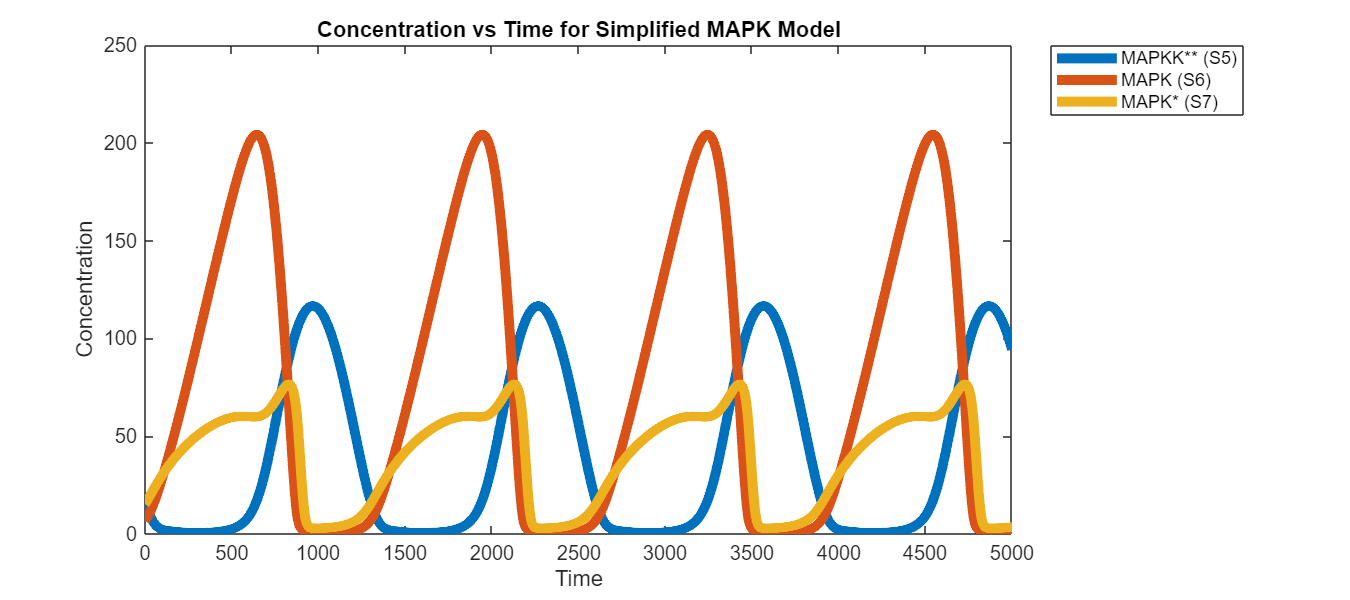

figure('Position',[100 100 900 400]);
hold on
for i = 1:numel(investigate_index)
    plot(t, sol(:, investigate_index(i)), 'LineWidth', 5, ...
        'DisplayName', investigate_label{i});
end
hold off

xlim([0, 5000]);
xticks(0:500:5000);

ylim([0, 250]);
yticks(0:50:250);

xlabel('Time');
ylabel('Concentration');
title('Concentration vs Time for Simplified MAPK Model');
legend('Location','northeastoutside');  % similar to Python legend outside
box on

### **Detect loop structures:**

[loop_rep, loop_rep_index, jac_rep, jac_rep_index] =find_loops_vset(@(x)func_kho00(1,x,klin,kn),sol',1000);
disp(loop_rep)

    {31×3 table}    {31×3 table}



disp(loop_rep_index)

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2    

sel_idx   = [5 6 7];
sel_label = {'MAPKK** (S5)', 'MAPK (S6)', 'MAPK* (S7)'};

% Safety: make sure indices are valid
assert(all(sel_idx >= 1 & sel_idx <= size(sol,2)), 'sel_idx out of range.');

% Extract selected trajectories (time x selected_states)
sol_sel = sol(:, sel_idx);

loop_id = loop_rep_index(:);
disp('loop_rep_index and time_vec must match.'); disp(numel(loop_id)); disp(numel(t));

loop_rep_index and time_vec must match.
        5001

        5001



% Find segment boundaries where loop_id changes
change_idx = [1; find(diff(loop_id) ~= 0) + 1; numel(loop_id) + 1];

nSeg = numel(change_idx) - 1;
t_start = zeros(nSeg,1);
t_end   = zeros(nSeg,1);
seg_id  = zeros(nSeg,1);

for s = 1:nSeg
    i1 = change_idx(s);
    i2 = change_idx(s+1) - 1;
    t_start(s) = t(i1);
    t_end(s)   = t(i2);
    seg_id(s)  = loop_id(i1);
end

transition_times = t_end(1:end-1);


Plot:

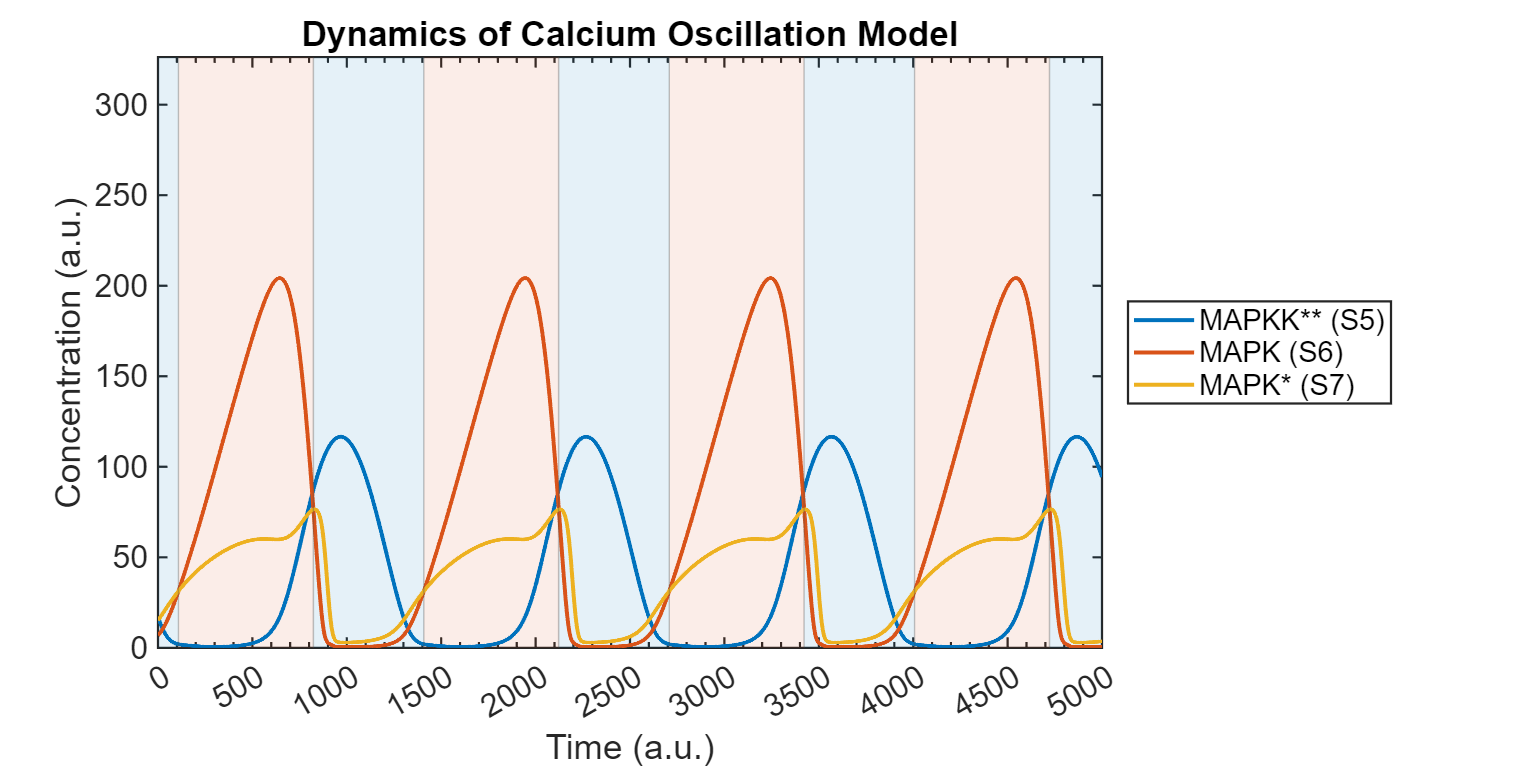

figure('Color','w', 'Position',[100 100 1200 600]); hold on;

% Set x-limits early (so patches cover the right region)
xlim([0 5000]); 
xlabel('Time (a.u.)');
ylabel('Concentration (a.u.)');
title('Dynamics of Calcium Oscillation Model');

% Get y-limits from data, then draw patches spanning full height
ymin = 0; % min(sol(:));
ymax = max(sol(:))*1.1;
ylim([ymin ymax]);

% Colors for loop structures (categorical palette)
uID = unique(seg_id, 'stable');
cmap = lines(numel(uID));  % quick palette; swap to brewermap if you prefer

% Background bands (behind lines): patch rectangles
for s = 1:nSeg
    cidx = find(uID == seg_id(s), 1);
    x = [t_start(s) t_end(s)   t_end(s)   t_start(s)];
    y = [ymin       ymin       ymax       ymax];
    patch(x, y, cmap(cidx,:), ...
        'EdgeColor','none', ...
        'FaceAlpha',0.10, ...
        'HandleVisibility','off'); % keep legend clean
end

% Vertical transition lines
for tt = transition_times(:)'
    xline(tt, '-', ...
        'Color', [0.3 0.3 0.3], ...
        'LineWidth', 0.7, ...
        'Alpha', 0.35, ...
        'HandleVisibility','off');
end

% Trajectories (only for selected params)
nSel = numel(sel_idx);
spec_colors = lines(nSel);
h = gobjects(nSel,1);

for j = 1:nSel
    h(j) = plot(t, sol_sel(:,j), 'LineWidth', 2, 'Color', spec_colors(j,:));
end

% Axis ticks like your ggplot scale_x_continuous
xticks(0:500:5000);
xlim([0 5000]);

% Styling similar to theme_minimal + border
set(gca, ...
    'FontSize', 16, ...
    'Box', 'on', ...
    'LineWidth', 1.1, ...
    'XMinorTick', 'on');
grid off;

% Legend for species (like scale_colour_manual)
legend(h, sel_label, 'Location','eastoutside');

### **Loop structures**

**Loop 1:**

disp(loop_summary(loop_rep{1}));

                length_1    length_2    length_3    length_4    length_5    length_6    length_7    length_8
                ________    ________    ________    ________    ________    ________    ________    ________

    total          8           5           1           3           5           5           3           1    
    negative       8           0           1           1           1           4           2           0    
    positive       0           5           0           2           4           1           1           1    



**Loop 2:**

disp(loop_summary(loop_rep{2})); 

                length_1    length_2    length_3    length_4    length_5    length_6    length_7    length_8
                ________    ________    ________    ________    ________    ________    ________    ________

    total          8           5           1           3           5           5           3           1    
    negative       8           0           1           2           1           2           3           0    
    positive       0           5           0           1           4           3           0           1    



### **Jacobian matrices:**

disp(jac_rep{1});

    -1     1     0     0     0     0     0     1
     1    -1     0     0     0     0     0    -1
     0    -1    -1     1     0     0     0     0
     0     1     1    -1     1     0     0     0
     0     1     0     1    -1     0     0     0
     0     0     0     0    -1    -1     1     0
     0     0     0     0    -1     1    -1     1
     0     0     0     0     1     0     1    -1



disp(jac_rep{2});

    -1     1     0     0     0     0     0     1
     1    -1     0     0     0     0     0    -1
     0    -1    -1     1     0     0     0     0
     0     1     1    -1     1     0     0     0
     0     1     0     1    -1     0     0     0
     0     0     0     0    -1    -1     1     0
     0     0     0     0     1     1    -1     1
     0     0     0     0     1     0     1    -1



## Without feedbacks

### Temporal dynamics

Solving the ODE model to observe temporal dynamics

There is no oscillation to stablize as compared to when there is feedback term. We only simulate until the system achieves its steady states.

tspan = linspace(0, 500, 501);
opts = odeset('RelTol',1e-6,'AbsTol',1e-9);  % closer to typical SciPy accuracy
[t,sol] = ode15s(@(t,x) func_kho00_nofb(t,x,klin, kn), tspan, initial_conditions, opts);

Plot

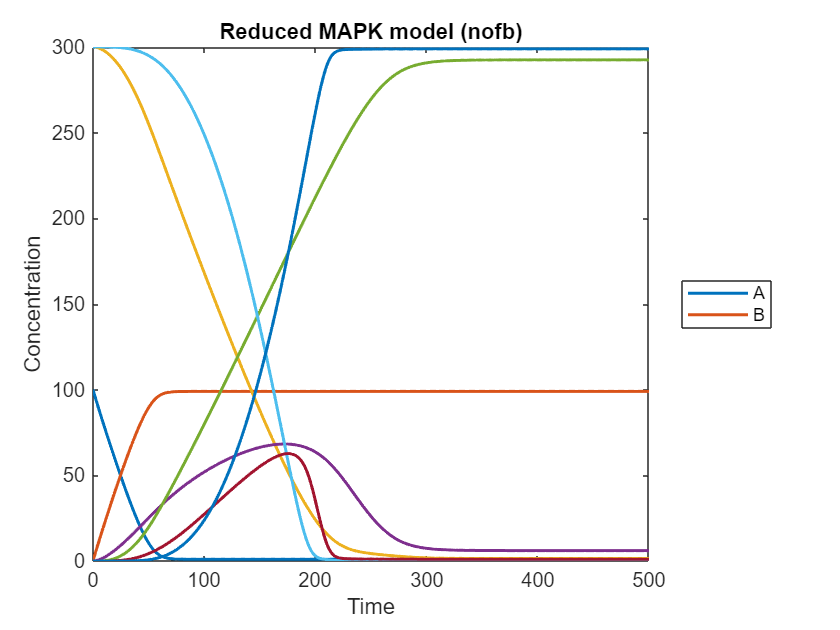

figure;
plot(t, sol, 'LineWidth', 1.5);
%xline(t_perb, '--', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Concentration');
xlim([0,500]);
% ylim([0,2]);
title('Reduced MAPK model (nofb)');
legend('A','B','Location','eastoutside'); % southeast

Extract selected variables:

investigate_label = {'MAPKK** (S5)', 'MAPK** (S8)'};
investigate_index = [5, 8];

Plot only selected variables:

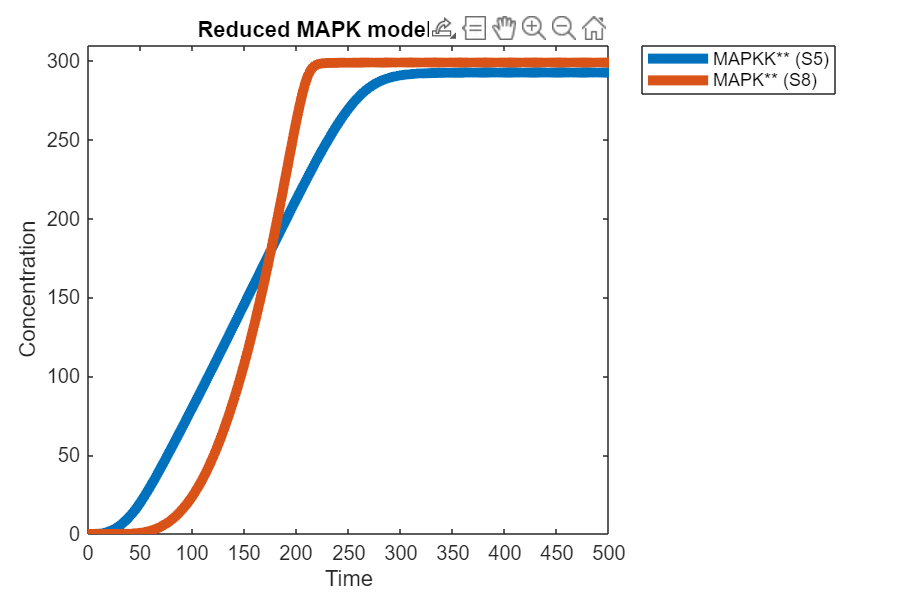

figure('Position',[100 100 600 400]);
hold on
for i = 1:numel(investigate_index)
    plot(t, sol(:, investigate_index(i)), 'LineWidth', 5, ...
        'DisplayName', investigate_label{i});
end
hold off

xlim([0, 500]);
xticks(0:50:500);

ylim([0, 310]);
yticks(0:50:310);

xlabel('Time');
ylabel('Concentration');
title('Reduced MAPK model (nofb)');
legend('Location','northeastoutside');  % similar to Python legend outside
box on

Loop Detect at steady states:

loop_rep = find_loops_vset(@(x)func_kho00_nofb(1,x,klin,kn),sol(end,:)',1000);
disp(loop_summary(loop_rep{1}));

                length_1    length_2
                ________    ________

    total          8           5    
    negative       8           0    
    positive       0           5    



## Export *.mlx to *.md / *.pdf

path = export("MATLAB/model_5_MAPK_reduced.mlx", "MATLAB/model_5_MAPK_reduced.pdf")

path = 'MATLAB\model_5_MAPK_reduced.pdf'

mdfile = export("MATLAB/model_5_MAPK_reduced.mlx","MATLAB/model_5_MAPK_reduced.md", Format="markdown", EmbedImages=true, ...
    AcceptHTML=true)

mdfile = 'MATLAB\model_5_MAPK_reduced.md'